# BPSK Modulator Simulation

## Theoretical background

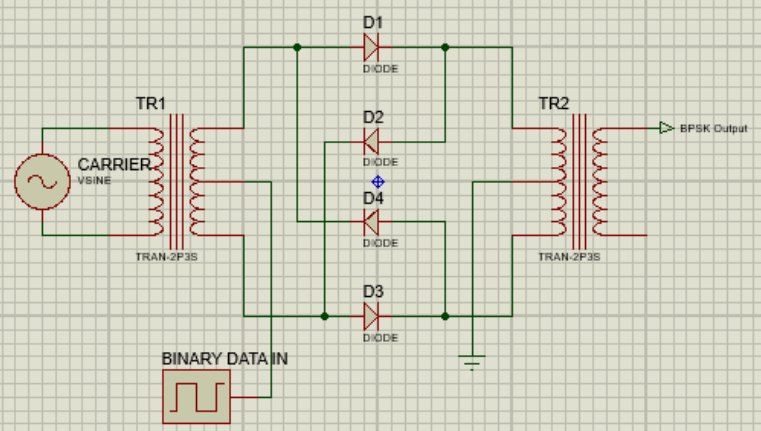

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform is a square wave of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

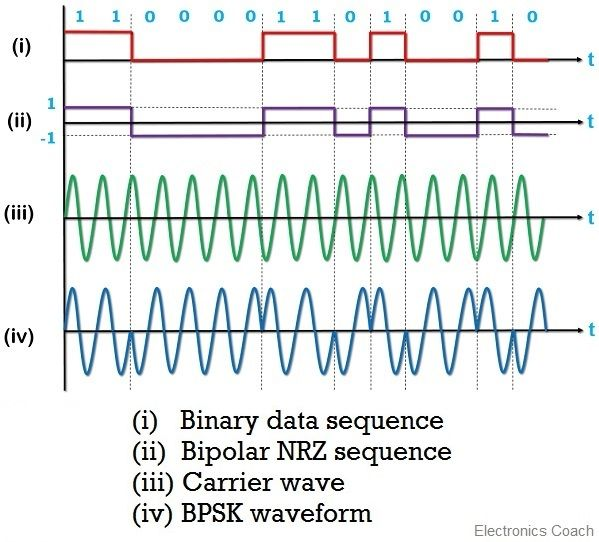

## Ideal balanced modulator simulation

### Carrier wave specifications

- A similar technology, IEEE 802.15. 4 (the wireless standard used by Zigbee) also relies on PSK using two frequency bands: **868–915 MHz with BPSK **and at 2.4 GHz with OQPSK. Both QPSK and 8PSK are widely used in satellite broadcasting. ([Phase-shift keying - Wikipedia](https://en.wikipedia.org/wiki/Phase-shift_keying#:~:text=A%20similar%20technology%2C%20IEEE%20802.15,widely%20used%20in%20satellite%20broadcasting.))

Ac = 10;
fc = 865.5e6;

### Binary data

n = 16;
bits = randi([0 1], [1 n])

bits =      0     0     1     0     1     1     1     1     0     1     0     0     0     0     0     1


### Time vector

spb = 50;
t = linspace(0, (length(bits))/fc, length(bits)*spb);

### Carrier wave

fs = fc*spb;
t_temp = 0 : 1/fs : length(bits)/fc - 1/fs;
carrier = Ac.*sin(2.*pi.*fc.*t_temp);

### Binary waveform

bin = zeros(1, length(bits)*spb);
for i = 1 : length(bits)
    bin((i-1)*spb + 1 : i*spb) = bits(i);
end

### NRZ waveform

nrz = zeros(1, length(bits)*spb);
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            nrz((i-1)*spb + 1 : i*spb) = 1;
        case 0
            nrz((i-1)*spb + 1 : i*spb) = -1;
    end
end

### BPSK modulator output

fs = fc*spb;
BPSK = zeros(size(bin));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            BPSK((i-1)*spb + 1 : i*spb) = carrier(1:spb);
        case 0
            BPSK((i-1)*spb + 1 : i*spb) = -carrier(1:spb);
    end
end

### Waveform plots

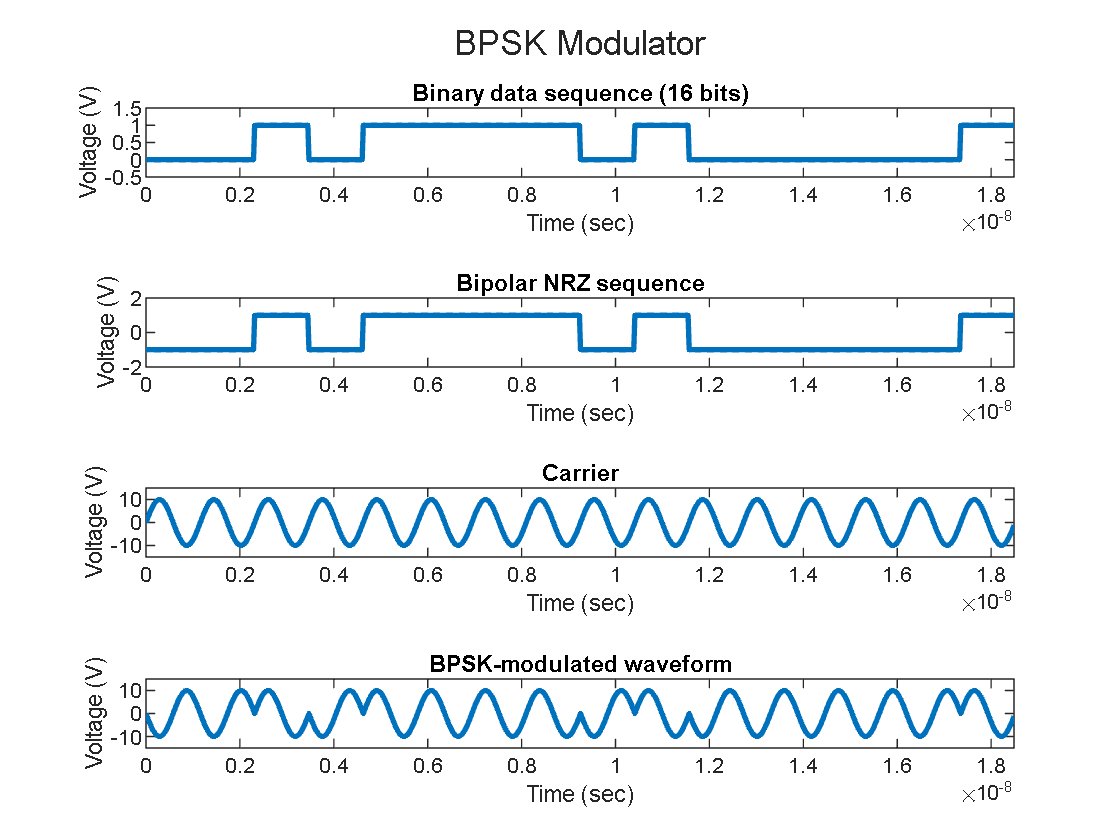

figure(1)
tiledlayout(4, 1)
sgtitle("BPSK Modulator")
 
nexttile
plot(t, bin, LineWidth=2)
title("Binary data sequence (" + num2str(n) + " bits)")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(t)])
ylim([-0.5 1.5])

nexttile
plot(t, nrz, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(t)])
ylim([-2 2])

nexttile
plot(t, carrier, LineWidth=2)
title("Carrier")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(t)])
ylim((Ac*(3/2)).*[-1 1])

nexttile
plot(t, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(t)])
ylim((Ac*(3/2)).*[-1 1])

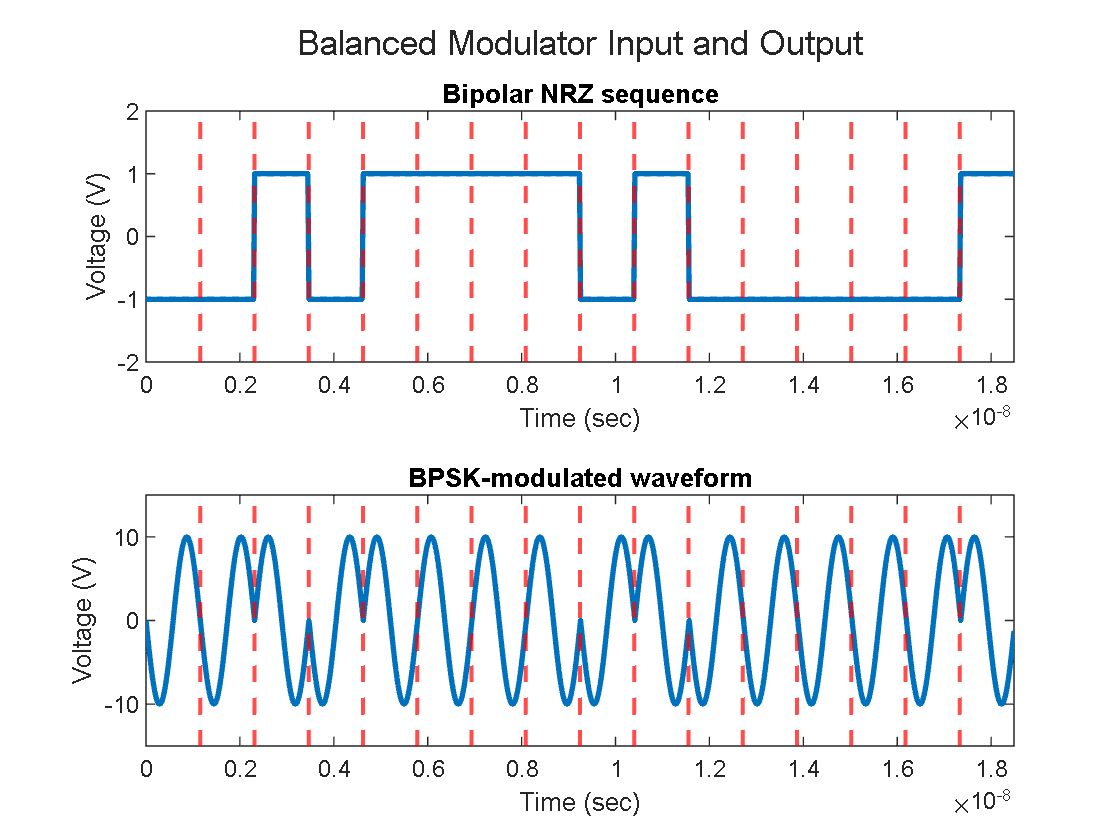


figure(2)
tiledlayout(2, 1)
sgtitle("Balanced Modulator Input and Output")

nexttile
plot(t, nrz, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
for i = 1 : length(bits)-1, xline(i/fc, LineStyle='--', Color='red', LineWidth=1.5); end
xlim([0 max(t)])
ylim([-2 2])

nexttile
plot(t, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
for i = 1 : length(bits)-1, xline(i/fc, LineStyle='--', Color='red', LineWidth=1.5); end
xlim([0 max(t)])
ylim((Ac*(3/2)).*[-1 1])

## BPSK complex envelope generator

### Binary data

nbits = 1e6;
bits = randi([0 1], 1, nbits)

bits =      0     0     1     0     1     1     1     1     1     0     1     0     0     1     1     1     0     0     0     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     1     1     0     0     1     1     0     1


### Modulation & Complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            cmplx_env(i) = -1;
        case 0
            cmplx_env(i) = 1;
        otherwise
            error("Error in bit generation")
    end
end
cmplx_env = complex(cmplx_env)

cmplx_env =    1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i


### Additive white Gaussian noise

SNR = 5;   
noise_cmplx_env = awgn(cmplx_env, SNR)

noise_cmplx_env =    0.4356 - 0.4705i   0.7464 - 0.5819i  -0.9059 + 0.0916i   1.2422 + 0.1063i  -0.8555 + 0.3368i  -1.6230 + 0.0316i  -0.7583 - 0.0288i  -1.4588 - 0.0459i  -0.1923 + 0.0179i   1.0839 + 0.0704i  -1.5302 - 0.3537i   1.1674 - 0.1773i   0.9442 - 0.2890i  -1.1492 - 0.6940i  -0.8519 - 0.0053i  -1.2433 + 0.5986i   0.9558 + 0.1143i   1.0646 + 0.2967i   0.7290 - 0.3322i  -1.2152 - 0.4497i  -1.3965 + 0.3335i   0.6833 + 0.4424i   1.4895 + 0.7782i   1.2958 - 0.3718i   0.9622 - 0.2856i  -1.1671 + 0.5816i  -0.8452 + 0.4089i  -1.2986 + 0.0615i  -1.0349 + 0.9816i  -0.9488 + 0.0642i  -1.1497 + 0.6082i  -1.1903 + 0.0929i  -1.4387 + 0.1454i  -0.7700 + 0.3072i  -1.6146 - 0.4443i  -1.0306 + 0.1634i  -0.7729 - 0.2431i  -0.5528 + 0.0656i  -1.2222 - 0.2756i   0.5177 + 0.1281i  -1.0506 + 0.1678i   0.8553 + 0.4038i  -0.4418 + 0.2903i  -1.9434 - 0.0975i   1.1430 + 0.4149i   0.8051 - 0.2320i  -0.5509 - 0.0007i  -1.3446 + 0.0958i   1.1212 - 0.2709i  -0.9073 - 0.1412i


### Constellation diagram

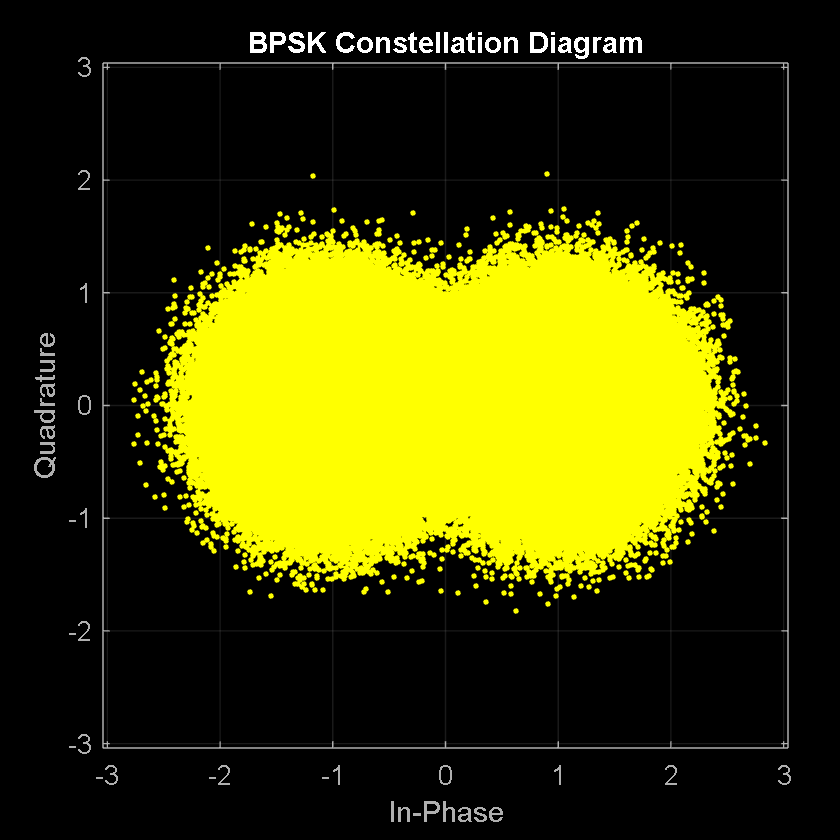

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Demodulation

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) < 0
        recovered_bits(i) = 1;
    elseif real(noise_cmplx_env(i)) >= 0 
        % do nothing since array is already zeros
    else
        error("Error in complex envelope generation")
    end
end
recovered_bits

recovered_bits =      0     0     1     0     1     1     1     1     1     0     1     0     0     1     1     1     0     0     0     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     1     1     0     0     1     1     0     1


### System performance: Bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 5, the BPSK modulation system produced 6021 number of bits in error. Resulting BER is 0.6021 percent.

## BPSK complex envelope generator using built-in functions

### BPSK modulation with pskmod()

complex_envelope = pskmod(bits, 2) % uses the same bits from previous section

complex_envelope =    1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i


### Additive white Gaussian noise

noise_complex_envelope = awgn(complex_envelope, SNR)

noise_complex_envelope =    1.0669 + 0.0969i   0.7725 + 0.7520i  -1.9861 + 0.3516i   0.9901 - 0.1286i  -0.8465 - 0.0890i  -1.1467 - 0.1694i  -0.7412 - 0.5220i  -0.8555 + 0.1952i  -1.1851 - 0.1438i   0.8493 - 0.2806i  -1.1583 - 0.1868i   0.8501 + 0.4803i   0.7240 + 0.0549i  -1.0058 - 0.2870i  -0.5387 + 0.9381i  -1.1042 - 0.2536i   1.4015 - 0.4758i   1.6275 - 0.2151i   0.9971 + 0.0764i  -1.0606 - 0.3338i  -0.6711 + 0.8892i   0.9657 - 0.4661i   1.3136 - 0.7309i   0.7471 - 0.1023i   1.1702 - 0.2408i  -0.7104 + 0.2073i  -1.2279 - 0.0557i  -0.8358 - 0.3085i  -0.6349 + 0.3461i  -1.1752 - 0.1958i  -1.2753 + 0.5849i  -1.4053 + 0.0895i  -0.3275 - 0.5488i  -0.4774 - 0.0321i  -1.8129 + 0.0578i  -1.1385 - 0.0649i  -1.3582 - 0.4418i  -1.1538 + 0.2283i  -0.4447 - 0.4361i   1.2646 + 0.7562i  -1.1409 + 0.5463i   1.2000 - 0.0945i  -0.8494 - 0.3986i  -0.5411 - 0.6138i   0.9267 - 0.4657i   1.0431 - 0.6513i  -0.6706 - 0.2659i  -1.7370 - 0.3646i   1.2627 - 0.1918i  -0.9293 + 0.5624i


### Constellation diagram

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Demodulation

recovered_bits = pskdemod(noise_cmplx_env, 2)

recovered_bits =      0     0     1     0     1     1     1     1     1     0     1     0     0     1     1     1     0     0     0     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     1     1     0     0     1     1     0     1


### System performance: Bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 5, the BPSK modulation system produced 6021 number of bits in error. Resulting BER is 0.6021 percent.